load('area_pre_tutti_et1_p1.mat')
load('area_post_tutti_et1_p1.mat')
load('area_pre_tutti_et1_p2.mat')
load('area_post_tutti_et1_p2.mat')

load('area_pre_tutti_sham_p1.mat')
load('area_post_tutti_sham_p1.mat')
load('area_pre_tutti_sham_p2.mat')
load('area_post_tutti_sham_p2.mat')

p_p1_et1=area_pre_tutti_et1_p1\area_post_tutti_et1_p1

p_p1_et1 = 0.5670

fit_area_post_p1_et1=p_p1_et1*[0; area_pre_tutti_et1_p1];

p_p2_et1=area_pre_tutti_et1_p2\area_post_tutti_et1_p2

p_p2_et1 = 0.7737

fit_area_post_p2_et1=p_p2_et1*[0;area_pre_tutti_et1_p2];

p_p1_sham=area_pre_tutti_sham_p1\area_post_tutti_sham_p1

p_p1_sham = 0.6863

fit_area_post_p1_sham=p_p1_sham*[0;area_pre_tutti_sham_p1];

p_p2_sham=area_pre_tutti_sham_p2\area_post_tutti_sham_p2

p_p2_sham = 0.8427

fit_area_post_p2_sham=p_p2_sham*[0;area_pre_tutti_sham_p2];

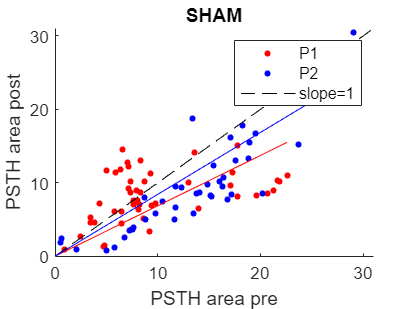

%plot dei due sham
figure
line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_sham_p2,area_post_tutti_sham_p2,'color','b','linestyle','none','marker','.','MarkerSize',10)
plot([0 31],[0 31],'k','LineStyle','--')
plot([0;area_pre_tutti_sham_p1],fit_area_post_p1_sham,'r')
plot([0;area_pre_tutti_sham_p2],fit_area_post_p2_sham,'b')
hold off
xlim([0 31])
ylim([0 31])
legend('P1','P2','slope=1')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('sham'))
box off

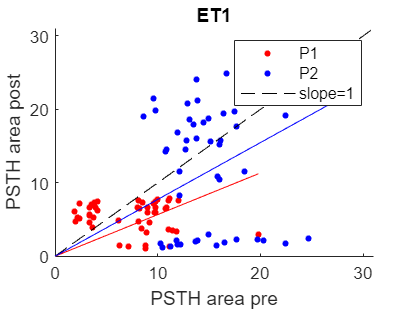

% plot dei due et1
figure
line(area_pre_tutti_et1_p1,area_post_tutti_et1_p1,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_et1_p2,area_post_tutti_et1_p2,'color','b','linestyle','none','marker','.','MarkerSize',10)
plot([0 31],[0 31],'k','LineStyle','--')
plot([0; area_pre_tutti_et1_p1],fit_area_post_p1_et1,'r')
plot([0;area_pre_tutti_et1_p2],fit_area_post_p2_et1,'b')
hold off
xlim([0 31])
ylim([0 31])
legend('P1','P2','slope=1')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('et1'))
box off

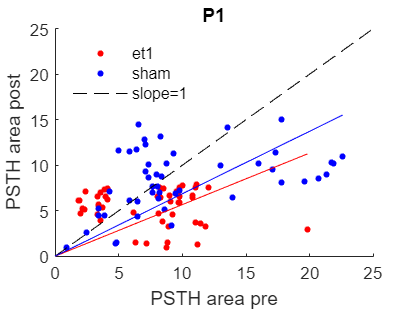

%plot dei due P1
figure
line(area_pre_tutti_et1_p1,area_post_tutti_et1_p1,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','b','linestyle','none','marker','.','MarkerSize',10)
plot([0 25],[0 25],'k','LineStyle','--')
plot([0; area_pre_tutti_et1_p1],fit_area_post_p1_et1,'r')
plot([0; area_pre_tutti_sham_p1],fit_area_post_p1_sham,'b')
hold off
xlim([0 25])
ylim([0 25])
legend('et1','sham','slope=1','Location','northwest')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('p1'))
box off
legend box off

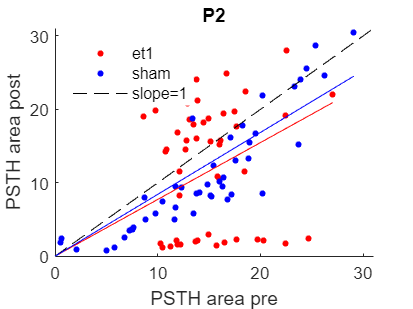

%plot dei due P2
figure
line(area_pre_tutti_et1_p2,area_post_tutti_et1_p2,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_sham_p2,area_post_tutti_sham_p2,'color','b','linestyle','none','marker','.','MarkerSize',10)
plot([0 31],[0 31],'k','LineStyle','--')
plot([0; area_pre_tutti_et1_p2],fit_area_post_p2_et1,'r')
plot([0; area_pre_tutti_sham_p2],fit_area_post_p2_sham,'b')
hold off
xlim([0 31])
ylim([0 31])
legend('et1','sham','slope=1','Location','northwest')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('p2'))
box off
legend box off

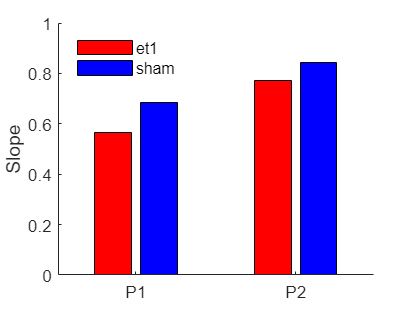

b=bar([p_p1_et1 p_p1_sham; ...
    p_p2_et1 p_p2_sham]);
b(1).FaceColor = [1 0 0];
b(2).FaceColor = [0 0 1];
title('')
% xlabel('channels [#]')
ylabel('Slope')
xticklabels({'P1','P2'})
box off
legend('et1','sham','Location','northwest')
legend box off

p_rat1_p1_et1=area_pre_tutti_et1_p1(1:16)\area_post_tutti_et1_p1(1:16)

p_rat1_p1_et1 = 0.6936

fit_area_post_rat1_p1_et1=p_rat1_p1_et1*[0; area_pre_tutti_et1_p1(1:16)];

p_rat1_p2_et1=area_pre_tutti_et1_p2(1:16)\area_post_tutti_et1_p2(1:16)

p_rat1_p2_et1 = 1.1034

fit_area_post_rat1_p2_et1=p_rat1_p2_et1*[0; area_pre_tutti_et1_p2(1:16)];

p_rat2_p1_et1=area_pre_tutti_et1_p1(17:32)\area_post_tutti_et1_p1(17:32)

p_rat2_p1_et1 = 1.8614

fit_area_post_rat2_p1_et1=p_rat2_p1_et1*[0; area_pre_tutti_et1_p1(17:32)];

p_rat2_p2_et1=area_pre_tutti_et1_p2(17:32)\area_post_tutti_et1_p2(17:32)

p_rat2_p2_et1 = 1.1702

fit_area_post_rat2_p2_et1=p_rat2_p2_et1*[0; area_pre_tutti_et1_p2(17:32)];

p_rat3_p1_et1=area_pre_tutti_et1_p1(33:48)\area_post_tutti_et1_p1(33:48)

p_rat3_p1_et1 = 0.3173

fit_area_post_rat3_p1_et1=p_rat3_p1_et1*[0; area_pre_tutti_et1_p1(33:48)];

p_rat3_p2_et1=area_pre_tutti_et1_p2(33:48)\area_post_tutti_et1_p2(33:48)

p_rat3_p2_et1 = 0.1200

fit_area_post_rat3_p2_et1=p_rat3_p2_et1*[0; area_pre_tutti_et1_p2(33:48)];

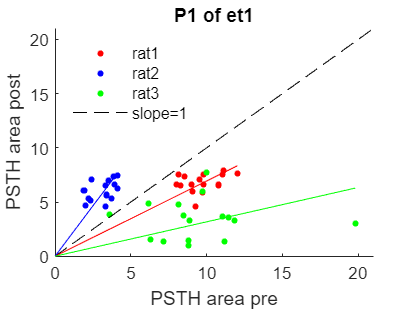

%plot dei P1 et1
figure
line(area_pre_tutti_et1_p1(1:16),area_post_tutti_et1_p1(1:16),'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
% line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_et1_p1(17:32),area_post_tutti_et1_p1(17:32),'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_et1_p1(33:48),area_post_tutti_et1_p1(33:48),'color','g','linestyle','none','marker','.','MarkerSize',10)
plot([0 21],[0 21],'k','LineStyle','--')
plot([0; area_pre_tutti_et1_p1(1:16)],fit_area_post_rat1_p1_et1,'r')
plot([0; area_pre_tutti_et1_p1(17:32)],fit_area_post_rat2_p1_et1,'b')
plot([0; area_pre_tutti_et1_p1(33:48)],fit_area_post_rat3_p1_et1,'g')
% plot([0; area_pre_tutti_sham_p1],fit_area_post_p1_sham,'b')
hold off
xlim([0 21])
ylim([0 21])
legend('rat1','rat2','rat3','slope=1','Location','northwest')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title('P1 of et1')
box off
legend box off

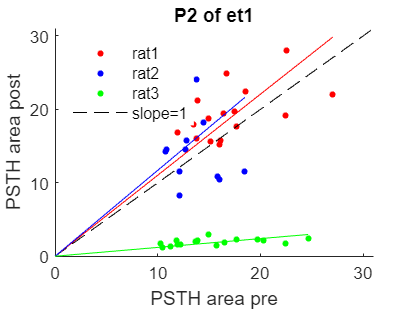

%plot dei P2 et1
figure
line(area_pre_tutti_et1_p2(1:16),area_post_tutti_et1_p2(1:16),'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
% line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_et1_p2(17:32),area_post_tutti_et1_p2(17:32),'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_et1_p2(33:48),area_post_tutti_et1_p2(33:48),'color','g','linestyle','none','marker','.','MarkerSize',10)
plot([0 31],[0 31],'k','LineStyle','--')
plot([0; area_pre_tutti_et1_p2(1:16)],fit_area_post_rat1_p2_et1,'r')
plot([0; area_pre_tutti_et1_p2(17:32)],fit_area_post_rat2_p2_et1,'b')
plot([0; area_pre_tutti_et1_p2(33:48)],fit_area_post_rat3_p2_et1,'g')
% plot([0; area_pre_tutti_sham_p1],fit_area_post_p1_sham,'b')
hold off
xlim([0 31])
ylim([0 31])
legend('rat1','rat2','rat3','slope=1','Location','northwest')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title('P2 of et1')
box off
legend box off

p_rat1_p1_sham=area_pre_tutti_sham_p1(1:16)\area_post_tutti_sham_p1(1:16)

p_rat1_p1_sham = 0.5493

fit_area_post_rat1_p1_sham=p_rat1_p1_sham*[0; area_pre_tutti_sham_p1(1:16)];

p_rat1_p2_sham=area_pre_tutti_sham_p2(1:16)\area_post_tutti_sham_p2(1:16)

p_rat1_p2_sham = 0.6076

fit_area_post_rat1_p2_sham=p_rat1_p2_sham*[0; area_pre_tutti_sham_p2(1:16)];

p_rat2_p1_sham=area_pre_tutti_sham_p1(17:32)\area_post_tutti_sham_p1(17:32)

p_rat2_p1_sham = 1.0568

fit_area_post_rat2_p1_sham=p_rat2_p1_sham*[0; area_pre_tutti_sham_p1(17:32)];

p_rat2_p2_sham=area_pre_tutti_sham_p2(17:32)\area_post_tutti_sham_p2(17:32)

p_rat2_p2_sham = 0.9760

fit_area_post_rat2_p2_sham=p_rat2_p2_sham*[0; area_pre_tutti_sham_p2(17:32)];

p_rat3_p1_sham=area_pre_tutti_sham_p1(33:48)\area_post_tutti_sham_p1(33:48)

p_rat3_p1_sham = 1.1733

fit_area_post_rat3_p1_sham=p_rat3_p1_sham*[0; area_pre_tutti_sham_p1(33:48)];

p_rat3_p2_sham=area_pre_tutti_sham_p2(33:48)\area_post_tutti_sham_p2(33:48)

p_rat3_p2_sham = 0.6074

fit_area_post_rat3_p2_sham=p_rat3_p2_sham*[0; area_pre_tutti_sham_p2(33:48)];

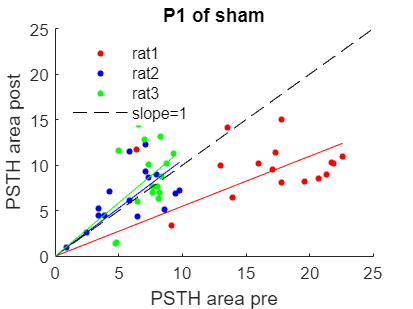

%plot dei P1 sham
figure
line(area_pre_tutti_sham_p1(1:16),area_post_tutti_sham_p1(1:16),'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
% line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_sham_p1(17:32),area_post_tutti_sham_p1(17:32),'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_sham_p1(33:48),area_post_tutti_sham_p1(33:48),'color','g','linestyle','none','marker','.','MarkerSize',10)
plot([0 25],[0 25],'k','LineStyle','--')
plot([0; area_pre_tutti_sham_p1(1:16)],fit_area_post_rat1_p1_sham,'r')
plot([0; area_pre_tutti_sham_p1(17:32)],fit_area_post_rat2_p1_sham,'b')
plot([0; area_pre_tutti_sham_p1(33:48)],fit_area_post_rat3_p1_sham,'g')
% plot([0; area_pre_tutti_sham_p1],fit_area_post_p1_sham,'b')
hold off
xlim([0 25])
ylim([0 25])
legend('rat1','rat2','rat3','slope=1','Location','northwest')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title('P1 of sham')
box off
legend box off

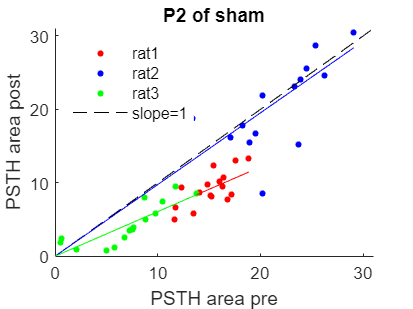

%plot dei P2 sham
figure
line(area_pre_tutti_sham_p2(1:16),area_post_tutti_sham_p2(1:16),'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
% line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_sham_p2(17:32),area_post_tutti_sham_p2(17:32),'color','b','linestyle','none','marker','.','MarkerSize',10)
line(area_pre_tutti_sham_p2(33:48),area_post_tutti_sham_p2(33:48),'color','g','linestyle','none','marker','.','MarkerSize',10)
plot([0 31],[0 31],'k','LineStyle','--')
plot([0; area_pre_tutti_sham_p2(1:16)],fit_area_post_rat1_p2_sham,'r')
plot([0; area_pre_tutti_sham_p2(17:32)],fit_area_post_rat2_p2_sham,'b')
plot([0; area_pre_tutti_sham_p2(33:48)],fit_area_post_rat3_p2_sham,'g')
% plot([0; area_pre_tutti_sham_p1],fit_area_post_p1_sham,'b')
hold off
xlim([0 31])
ylim([0 31])
legend('rat1','rat2','rat3','slope=1','Location','northwest')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title('P2 of sham')
box off
legend box off

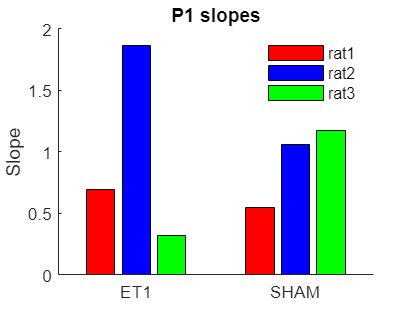

% BAR PLOT p1

b1=bar([p_rat1_p1_et1 p_rat2_p1_et1 p_rat3_p1_et1; ...
    p_rat1_p1_sham p_rat2_p1_sham p_rat3_p1_sham]);
b1(1).FaceColor = [1 0 0];
b1(2).FaceColor = [0 0 1];
b1(3).FaceColor = [0 1 0];

title('P1 slopes')
% xlabel('channels [#]')
ylabel('Slope')
xticklabels({'ET1','SHAM'})
box off
legend('rat1','rat2','rat3','Location','northeast')
legend box off

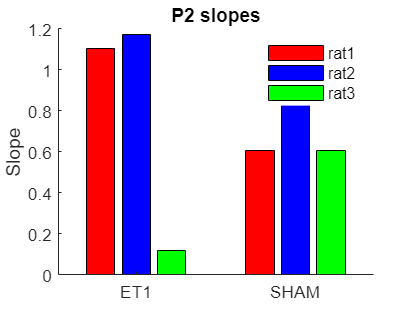

% BAR PLOT p2
b2=bar([p_rat1_p2_et1 p_rat2_p2_et1 p_rat3_p2_et1; ...
    p_rat1_p2_sham p_rat2_p2_sham p_rat3_p2_sham]);
b2(1).FaceColor = [1 0 0];
b2(2).FaceColor = [0 0 1];
b2(3).FaceColor = [0 1 0];

title('P2 slopes')
% xlabel('channels [#]')
ylabel('Slope')
xticklabels({'ET1','SHAM'})
box off
legend('rat1','rat2','rat3','Location','northeast')
legend box off

% verificare differenza statistica tra le curve--> h=1 distribuzioni sono
% diverse statisticamente
all_slope_p1_et1=[p_rat1_p1_et1;p_rat2_p1_et1;p_rat3_p1_et1];
all_slope_p2_et1=[p_rat1_p2_et1;p_rat2_p2_et1;p_rat3_p2_et1];
all_slope_p1_sham=[p_rat1_p1_sham;p_rat2_p1_sham;p_rat3_p1_sham];
all_slope_p2_sham=[p_rat1_p2_sham;p_rat2_p2_sham;p_rat3_p2_sham];

[h,p] = ttest2(all_slope_p1_et1,all_slope_p1_sham)

h = 0

p = 0.9538

[h,p] = ttest2(all_slope_p2_et1,all_slope_p2_sham)

h = 0

p = 0.8607


%%NON HA DETTO DI FARLE MA NEL CASO SERVISSERO

% verificare omogeneità della varianza --> h=1 se non vengono da
% distribuzioni normali con la stessa varianza, h=0 se l'h0 viene
% 'accettata' nel senso che c'è la possibilità che vengano da distribuzioni
% normali con stessa varianza ma questo non è certo ---> p=probabilità
% della null ipotesi
[h,p] = vartest2(all_slope_p1_et1,all_slope_p1_sham)

h = 0

p = 0.2903

[h,p] = vartest2(all_slope_p2_et1,all_slope_p2_sham)

h = 0

p = 0.2315